addpath('Utility_functions')

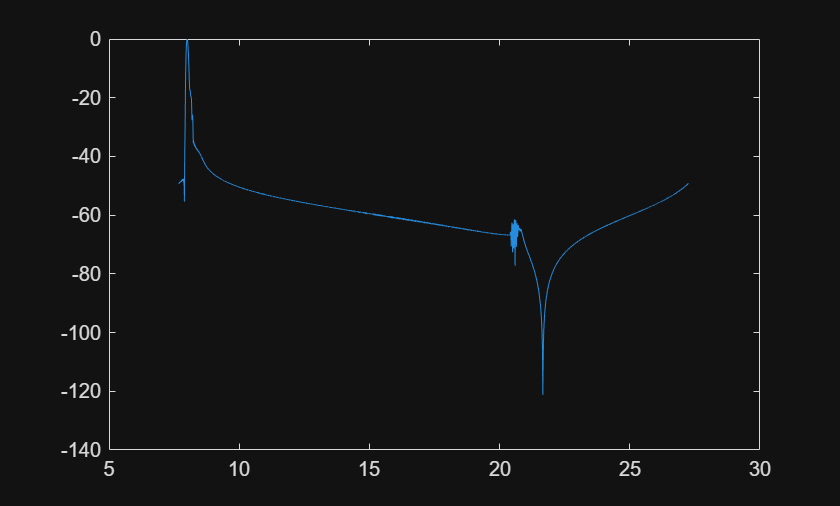

load("..\..\Data\FieldII_sims\field_ii_l2214_plane_input_0.mat")
% load('field_ii_l2214_4point.mat')
transmit_fnum = 6;


ts = t + dt*(0:(length(IRM)-1));
IRMshift = circshift(IRM,-18,3);
RM = FMCtoFocused_frequency(IRMshift,1.48,100,Trans,8,transmit_fnum,'a_shrink','hanning');
zs = ts*1480*1000/2;
xs = ((-(Trans.numelements/2 -1):(Trans.numelements/2))-0.5)*Trans.spacingMm;
figure()
plot(zs,20*log10(abs(squeeze(IRMshift(64,64,:))))-max(20*log10(abs(squeeze(IRMshift(64,64,:))))))

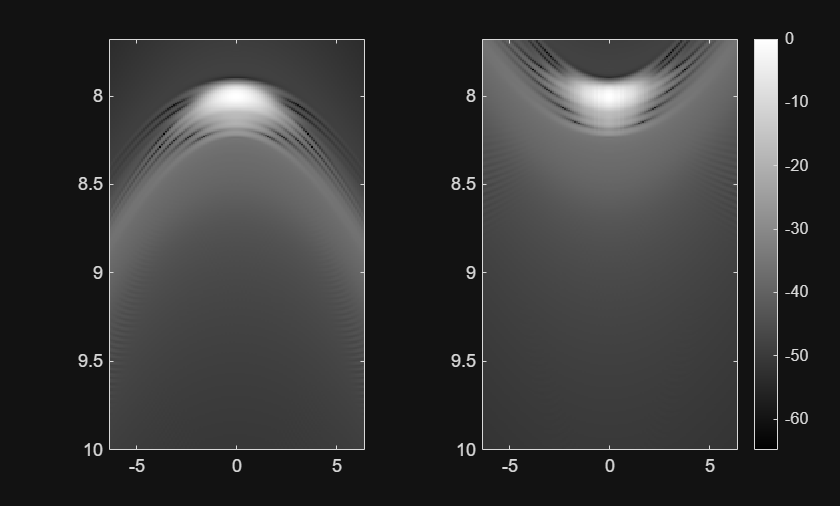

deltam = Trans.spacingMm;
deltams = (0:127)*deltam;
ts_temp = repmat(ts*1e6,length(deltams),1).';
zs_temp = repmat(zs,length(deltams),1).';
% t_delays = 0.5*(ts_temp + sqrt(ts_temp.^2 + 4*(deltams/1.48).^2)).';
t_delays = (zs_temp/1.48 + sqrt((zs_temp/1.48).^2 + (deltams/1.48).^2)).';
% t_delays = (2*sqrt((zs_temp).^2 + (deltams/2).^2)).'/1.48;
figure()
tiledlayout(1,2)
mask = zs < 10;


nexttile;
imagesc(xs,zs(mask),20*log10(abs(squeeze(RM(64,:,mask)).')) - max(max(20*log10(abs(squeeze(RM(64,:,mask)).')))))
colormap gray
% colorbar
% title(['source = ' num2str(source)])

for source = [64]
    j= 64;
    frame = squeeze(RM(j,:,:));
    % frame = squeeze(IRMshift(source,:,:));
    
    for i=1:128
        frame(i,:) = interp1(ts*1e6,frame(i,:),t_delays(1 + abs(j - i),:));
    end
    
    
    % figure()
    % tiledlayout(1,2);
    % nexttile;
    % mask = zs<10;
    % % imagesc(xs,zs(mask),log(abs(squeeze(RM(j,:,mask)).')))
    % imagesc(xs,zs(mask),log(abs(squeeze(IRMshift(j,:,mask)).')))
    % colormap gray
    % colorbar
    nexttile;
    imagesc(xs,zs(mask),20*log10(abs(frame(:,mask)).') - max(max(20*log10(abs(frame(:,mask)).'))))
    colormap gray
    colorbar
    % title(['source = ' num2str(source)])
end

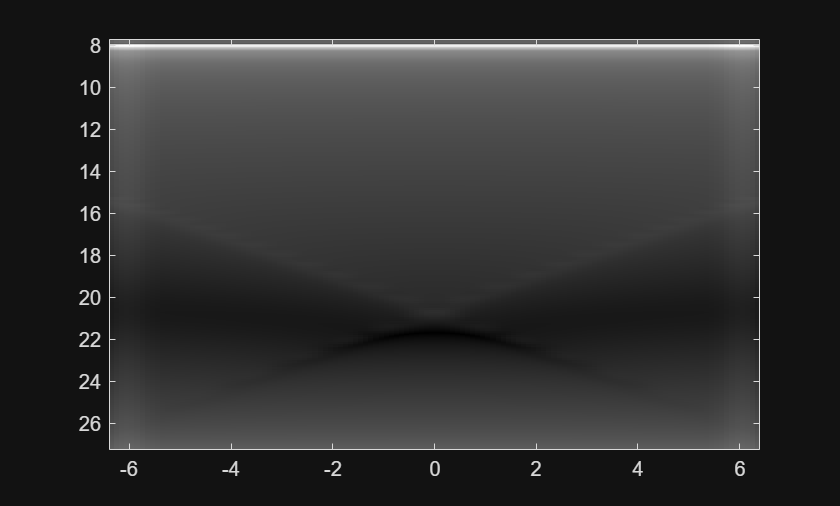

figure()
[das_data_small,xs,zs] = das(RM,t* 1e6,1.48,Trans,100,8,4,'a_shrink','hamming');
das_data_small = das_data_small/max(max(abs(das_data_small)));
bmode = 20*log10(abs(das_data_small).' +1e-4) - max(max(20*log10(abs(das_data_small).' +1e-4)));
imagesc(xs,zs,bmode)
colormap gray

recieve_fnums = [1 4 9];
ave_aline_normal = zeros(length(recieve_fnums),length(IRM));
channels = cell(length(recieve_fnums),1);
for i=1:length(recieve_fnums)
    [das_data_small,xs,zs] = das(RM,t* 1e6,1.48,Trans,100,8,recieve_fnums(i),'a_shrink','hamming');
    das_data_small = das_data_small/max(max(abs(das_data_small)));
    bmode = 20*log10(abs(das_data_small).' +1e-4) - max(max(20*log10(abs(das_data_small).' +1e-4)));
    ave_aline_normal(i,:) = mean(bmode(:,64 + (-20:20)),2) - max(max(mean(bmode(:,64 + (-20:20)),2)));
end

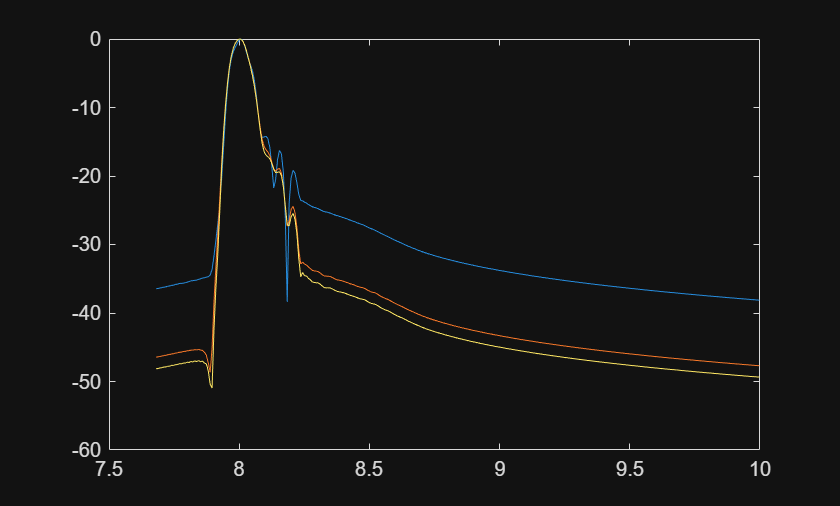

figure()
plot(zs(zs<10),ave_aline_normal(:,zs<10))

im1 = plot_profiles(6,[1 4 9]);

Out of memory.

Error in ifftshift (line 25)
    x = circshift(x,ceil(size(x,dim)/2),dim);

Error in FMCtoFocused_frequency (line 108)
RM = ifft(ifftshift(squeeze(FRM),3),len,3) * nelems / factor;

Error in 

im2 = plot_profiles(4,[1 4 9]);
im3 = plot_profiles(1,[1 4 9]);


function b_mode = log_compress(frame)

    b_mode = 20*log10(abs(squeeze(frame)).') - max(max(20*log10(abs(squeeze(frame)).')));

end

function im = plot_profiles(transmit_fnum, recieve_fnums)

    S = load("..\..\Data\FieldII_sims\field_ii_l2214_plane_input_0.mat");
    % transmit_fnum = 6;
    RM = FMCtoFocused_frequency(S.IRM,1.48,100,S.Trans,8,transmit_fnum,'a_shrink','hamming');
    % recieve_fnums = [1 4 9];
    ave_aline_normal = zeros(length(recieve_fnums),length(S.IRM));
    for i=1:length(recieve_fnums)
        [das_data_small,xs,zs] = das(RM,S.t * 1e6,1.48,S.Trans,100,8,recieve_fnums(i),'a_shrink','hamming');
        das_data_small = das_data_small/max(max(abs(das_data_small)));
        bmode = 20*log10(abs(das_data_small).' +1e-4) - max(max(20*log10(abs(das_data_small).' +1e-4)));
        ave_aline_normal(i,:) = mean(bmode(:,64 + (-20:20)),2) - max(max(mean(bmode(:,64 + (-20:20)),2)));
    end
    S = load("..\..\Data\FieldII_sims\scaled_onethird_IRM_3xfootprint.mat");
    RM = FMCtoFocused_frequency(S.IRM,1.48,100,S.Trans,8,transmit_fnum,'a_shrink','hamming');
    ave_aline_onethird = zeros(length(recieve_fnums),length(S.IRM));
    for i=1:length(recieve_fnums)
        [das_data_small,xs,zs] = das(RM,S.t * 1e6,1.48,S.Trans,100,8,recieve_fnums(i),'a_shrink','hamming');
        das_data_small = das_data_small/max(max(abs(das_data_small)));
        bmode = 20*log10(abs(das_data_small).' +1e-4) - max(max(20*log10(abs(das_data_small).' +1e-4)));
        ave_aline_onethird(i,:) = mean(bmode(:,194 + (-60:60)),2) - max(max(mean(bmode(:,194 + (-60:60)),2)));
    end
    figure()
    hold on
    plot(zs(zs<9),ave_aline_normal(:,zs<9),'LineWidth',2)
    plot(zs(zs<9),ave_aline_onethird(:,zs<9),'--','LineWidth',2)
    hold off
    legend({'1', '4', '9', '1, 1/3', '4, 1/3', '9, 1/3'})
    title(['F/' num2str(transmit_fnum) ' transmit, various recieve for L22-14 and 1/3 pitch'])
    xlabel('mm')
    ylabel('Intensity dB')
    im = gca;
end